**Suficiencia de Control Digital**

**Arthur de La Lande**

Tenemos los datos de salida de una planta / une proceso (unidad voltios) en respuesta a un escalón de entrada en porcentajes. Consideramos que las unidades por defecto que utilizaremos en este estudio son los voltios para la salida, los porcentajes para la entrada, las segundas para el tiempo.

Realizar la identificación no paramétrica por el método POR (primer orden), registrando claramente ganancia K, constante de tiempo del sistema tau, y retardo theta.

**1) Validar gráficamente el modelo obtenido comparándolo contra los datos.**

filename="DatosPlanta.xlsx";
T=readtable(filename);

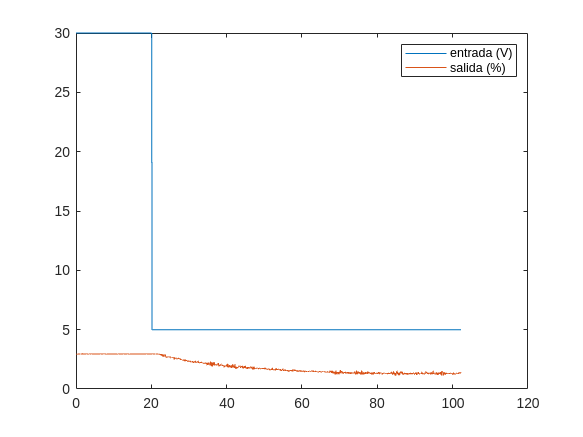

tiempo=T.Tiempo_s_;
salida=T.Salida_V_;
escalon=T.Entrada___;
plot(tiempo,escalon)
hold on
plot(tiempo,salida)
legend("entrada (V)","salida (%)")
hold off

Este grafico nos presenta la respuesta natural de la planta a un escalón inverso con un offset.

Graficamente, se puede suponer que el modelo de este sistema es un modelo de primer orden con retraso, porque :

- No tiene sobrepaso, pero no es suficiente para concluir la orden.

- La asimptota de la curva de salida no esta horizontal cuando inicia la reacción al escalón.

- Tiene un atraso en la salida comparado a la entrada.

La FTP es de la forma :

F(p)=exp(-tp)*K/(1+tau*p)

Donde K es la ganancia, t el atraso, tau el tiempo de respuesta del sistema.

Calculamos por el metodo POR el modelo de la planta (graficamente y con lo datos) :

steady_output=1.44;
init_output=2.95;
init_input=30;
steady_input=5;
K=(steady_output-init_output)/(steady_input-init_input) % en (V/%)

K = 0.0604

theta=22.40-20.20 % El retardo en s

theta = 2.2000

Buscamos tau. Es el tiempo desde el inicio del escalon cuando la curva de salida alcanza el 0.632 de la salida estable steady_output.

coef=0.632*(steady_output-init_output)+init_output

coef = 1.9957

Buscamos el tiempo al cual la curva alcanza "coef" y le restamos el momento inical del escalón y el atraso.

tau=38.1-theta-20.20

tau = 15.7000

La función de transferencia es :

F=tf(K,[tau,1],"InputDelay",theta)

F =
 
                  0.0604
  exp(-2.2*s) * ----------
                15.7 s + 1
 
Continuous-time transfer function.
Model Properties


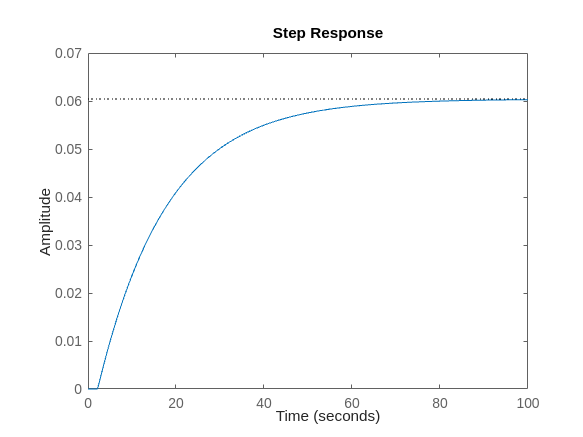

step(F)

**2) Discretizar el sistema por alguno de los 3 métodos: frecuencia, tiempo de establecimiento o tau equivalente.**

- Con el criterio de ancho de banda (frecuencia):

Buscamos la frecuencia de corte del modelo en lazo cerrado :

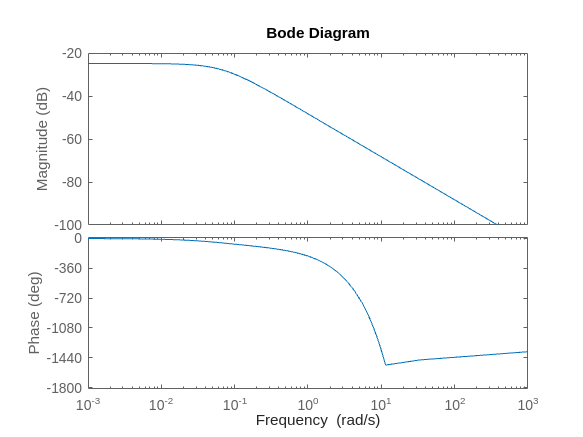

Flc=feedback(F,1); % El modelo de la planta en lazo cerrado.
bode(Flc)

El criterio de ancho de banda nos recomienda elegir ws para que respete : 8 wc < ws < 12 wc

Graficamente, se mide que el ancho de banda wc (frecuencia de corte a -3dB) se encuentra cuando la ganancia alcanza -28 dB, y vale aproximadamente 0.08 rad/s, entonces:

0.64 < ws < 0.96 rad/s.

Elegimos ws=0.95 rad/s, entonces :

Ts=2*pi/0.95 % s

Ts = 6.6139

Intentemos discretizarlo con otro metodo para comprobar el valor del tiempo de muestreo:

- Metodo de tiempo de establecimiento:

0,05 Te < Ts < 0,15 Te donde Te es el tiempo de establecimiento en lazo cerrado.

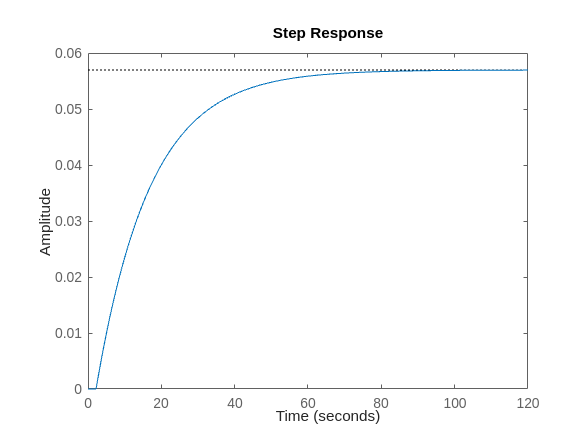

step(Flc)

Se mide Te cuando la curva alcanza 0.95*K=0.057 (escalon unitario).

se mide graficamente Te=90 s. Entonces:

4,5<Ts<13,5

Nos quedamos entonces con el Ts hallado por el criterio de ancho de banda.

Ts=6.6139;

**3) Registrar la FTP (función de transferencia discreta) obtenida y realizar comparación gráfica entre el modelo continuo y discreto.**

El hecho de que el tau de nuestro sistema sea mucho mayor que el atraso significa que el atraso no impacta la dinamica del sistema porque el transitorio es lento. Entonces, vamos a discretizar el modelo quitandolo el atraso ya que no impacta la dinamica. Es una simplificación que nos va a servir después.

F_sr=tf(K,[tau,1]) % La función de transferencia sin atraso (aproximación)

F_sr =
 
    0.0604
  ----------
  15.7 s + 1
 
Continuous-time transfer function.
Model Properties


Fd=c2d(F_sr,Ts) % La función de transferencia discretizada

Fd =
 
   0.02076
  ----------
  z - 0.6562
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


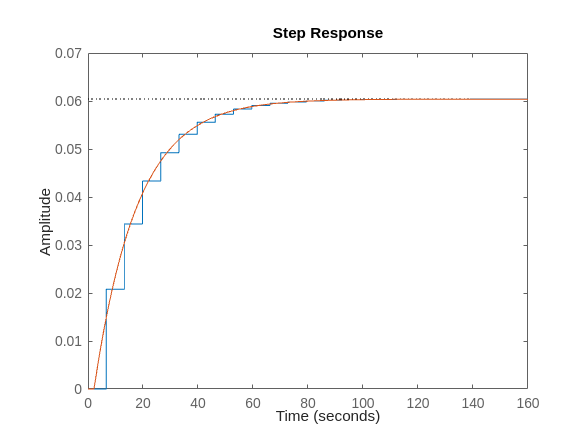

step(Fd)
hold on
step(F)
hold off

Se compara graficamente el modelo con el atraso y el modelo discretizado sin atraso y se comprueba que son muy cercanos. La aproximación que hicimos se ve adecuada.

**4) Realizar un análisis de estabilidad relativa por el método de Jury y determinar un rango adecuado para la ganancia.**

Buscamos los polos del sistema en lazo cerrado, quiere decir las raices del denominador del sistema el lazo cerrado, Q(z).

Fd_lc=feedback(Fd,1) % para una ganancia de 1

Fd_lc =
 
   0.02076
  ----------
  z - 0.6354
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


Igualamos la ecuación caracteristica a 0: Q(z)=1+k*F(z)*H(z)=0.

Donde:

- Q corresponde al denominador del sistema en lazo cerrado.

- en nuestro caso H=1 (retorno unitario).

- el valor de la ganancia k queda para definir.

Q(z) = z - 0,6562 + 0,02076*k =0

1. Se calcula Q(1) :

Q(1)= 1 - 0,6562 + 0,02076*k > 0

K > 0 entonces esta inegualdad no es critica.

2. se comprueba (-1)^n * Q(-1) > 0 donde n es el rango de Q.

-1 * (-1 - 0,6562 + 0,02076*k) > 0

k < 79,8

3. |a0|<|a1|

|- 0.8627 + 0.00829 * k|<1

Si  k > 31,6:

   - 0,6562 + 0,02076*k > 1

    k < 79,8

Si k < 31,6 :

 0,6562 - 0,02076*k > 1

  k < -16,5 pero k>0

En conclusión, 0 < k < 79,6 garantiza la estabilidad relativa del sistema.

**5) Diseñar 4 controladores: por el método de ganancia límite un PI y un PID, y por el método de curva de reacción un PI y un PID, simularlos.**

- **Metodo de ganacia limite o metodo de Ziegler-Nichols :**

En lazo abierto con retardo, leemos con el bode la magnitud para una fase de -180° (margen de ganancia)

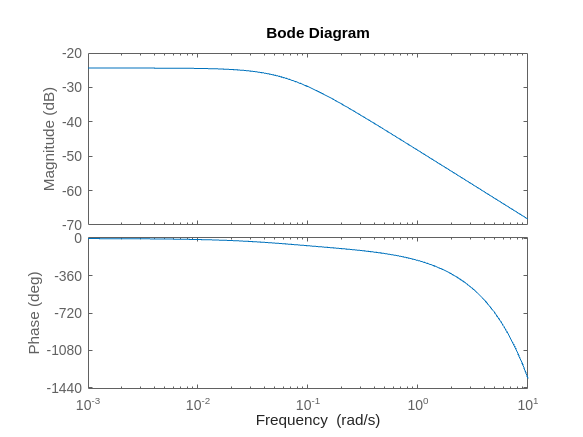

bode(F)

Buscamos la frecuencia cuando la fase alcanza -180°. Vale 0,75 rad/s.

En esta frecuencia se lee -28,17 dB = 20 log(MG)

La ganancia limite vale 1/MG:

Ku=1/10^(-28.17/20)

Ku = 25.6153

Calculamos la frecuencia de osilación constante en el bode:

Tu=2*pi/0.75

Tu = 8.3776

A. Para un PI

Kp_pi=0.45*Ku, Ti_pi=0.83*Tu

Kp_pi = 11.5269

Ti_pi = 6.9534

Comprobamos si el metodo es adecuado para nuestro sistema:

K*Ku<20 ?

0.0604*Ku

ans = 1.5472

Calculamos las constantes del controlador PI discretizado.

D_pi(z)=(q0*z+q1)/(z-1)

q0_pi=Kp_pi*(Ts/(2*Ti_pi)+1), q1_pi=Kp_pi*(Ts/(2*Ti_pi)-1)

q0_pi = 17.0090

q1_pi = -6.0448

B. Para un PID

Kp_pid=0.6*Ku, Ti_pid=0.5*Tu, Td=0.125*Tu

Kp_pid = 15.3692

Ti_pid = 4.1888

Td = 1.0472

q0_pid=Kp_pid*(1+Ts/(2*Ti_pid)+Td/Ts), q1_pid=Kp_pid*(Ts/(2*Ti_pid)-2*Td/Ts-1), q2=Kp_pid*Td/Ts

q0_pid = 29.9363

q1_pid = -8.1025

q2 = 2.4334

**2.  Por el metodo de curva de reacción**

Se hallan theta_p=theta+Ts/2

theta_p=2.2+Ts/2

theta_p = 5.5069

theta_p/tau

ans = 0.3508

Tenemos 0.1 < theta_p/tau < 1 entonces esta recomendado aplicar este metodo.

A. Para un PI

Kp_pi_cr=0.9*tau/(K*theta_p); Ti_pi_cr=3*theta_p

Ti_pi_cr = 16.5208

q0_pi_cr=Kp_pi_cr*(Ts/(2*Ti_pi_cr)+1); q1_pi_cr=Kp_pi_cr*(Ts/(2*Ti_pi_cr)-1)

q1_pi_cr = -33.9776

B. Para un PID

Kp_pid_cr=1.2*tau/(K*theta_p), Ti_pid_cr=2*theta_p, Td_cr=0.5*theta_p

Kp_pid_cr = 56.6412

Ti_pid_cr = 11.0139

Td_cr = 2.7535

q0_pid_cr=Kp_pid_cr*(1+Ts/(2*Ti_pid_cr)+Td_cr/Ts), q1_pid_cr=Kp_pid_cr*(Ts/(2*Ti_pid_cr)-2*Td_cr/Ts-1), q2_cr=Kp_pid_cr*Td_cr/Ts

q0_pid_cr = 97.2286

q1_pid_cr = -86.7959

q2_cr = 23.5807

**6) Seleccionar el que mejor desempeño tenga en cuanto a respuesta en el tiempo y acción de control. SI ningún controlador es estable, se debe estabilizar uno.**

Hagamos una simulación en Simulink con todos los controladores hallados para verificar sus depempeños.

Desempeño de los controladores hallados por Ziegler-Nichols:

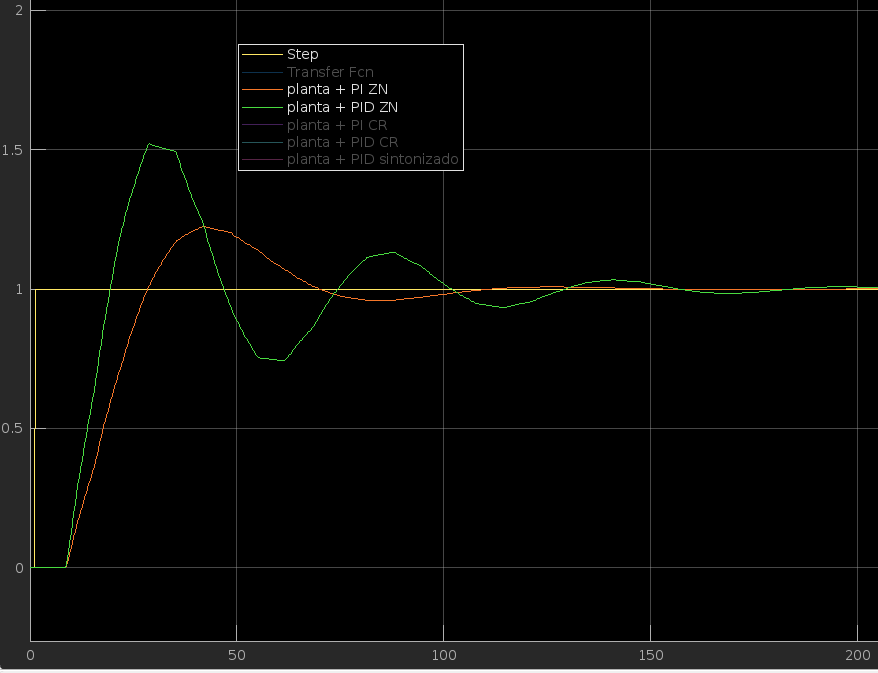

Fig: Desempeño de la planta en lazo cerrado con controladores PI y PID (Ziegler-Nichols) ante una entrada escalón unitaria.

El PI tiene bien mejor desempeño ya que tiene menos sobre impulsos y alcanza el estado estable mucho mas rapido (~60 s) contra 130 para el PID.

Desempeño de los controladores hallados por curva de reacción :

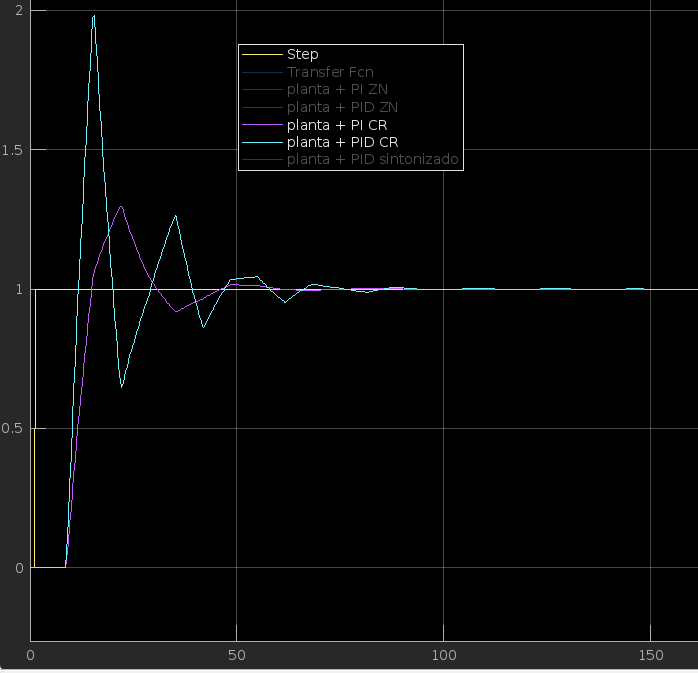

Fig: Desempeño de la planta en lazo cerrado con controladores PI y PID (curva de reacción) ante una entrada escalón unitaria.

Estos dos controladores son mucho mas nerviosos y rapidos que los hallados por ZN, ya que el mas rapido alcanza el estado estable en 50 s. El desempeño del PI en este supera lo del PID por tener menos sobreimpulsos, menos intensos, y alcanzar mas rapido el estado estable

Los 4 controladores son estables y precisos (el error es cero en estado estable).

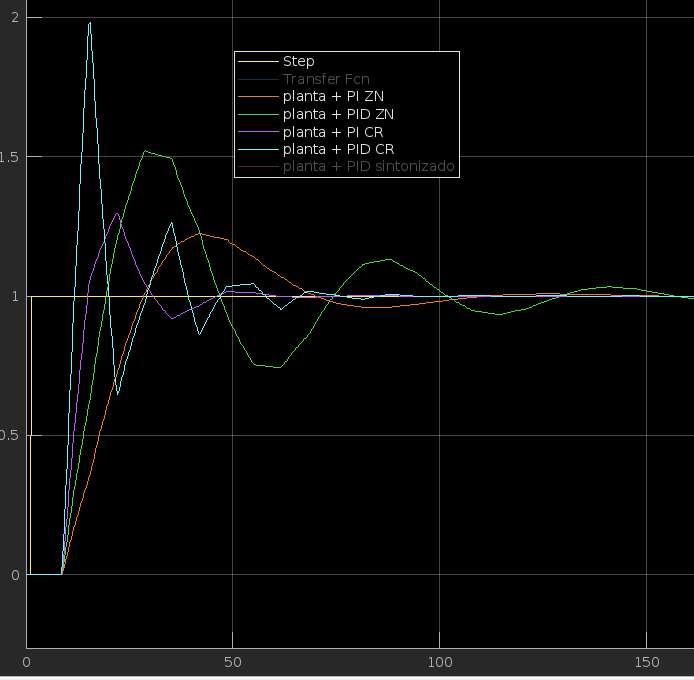

Fig: Desempeño de la planta en lazo cerrado con controladores PI y PID (curva de reacción y ZN) ante una entrada escalón unitaria.

En este ultimo grafico se puede comparar los desempeños de los cuatro controladores.

**7) Sintonizar el controlador seleccionado para que mejore el tiempo de establecimiento entre un 85 y 90% en comparación a lazo abierto, comprobar por simulación.**

Elegimos como controlador para sintonizar el controlador PI hallado por metodo de Ziegler-Nichols  (rojo). A pesar de que sea menos rapido, lo bueno de este controlador es que tiene un sobreimpulso menor (20%) comparado a los demas (100% para el "peor"), y que una vez sintonizado para mejorar su rapidez, tendria una buena rapidez ademas de un sobreimpulso bajo.

En lazo abierto, el tiempo de establecimiento es de 90 s. tenemos que tener a lo menos un tiempo de establecimiento con el controlador de un valor de 15% de 90s quiere decir 13,5s.

Kp_pi_s=28; Ti_pi_s=20;
q0_pi_s=Kp_pi_s*(Ts/(2*Ti_pi_s)+1), q1_pi_s=Kp_pi_s*(Ts/(2*Ti_pi_s)-1)

q0_pi_s = 32.6297

q1_pi_s = -23.3703

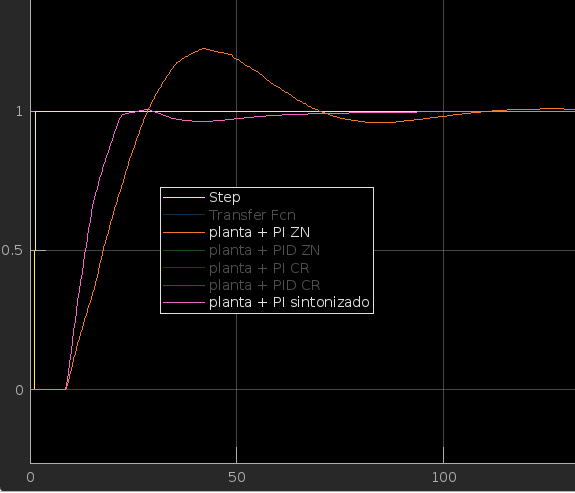

Fig: Desempeño de la planta en lazo cerrado con contorlador PI con metodo ZN y PI sintonizado ante una entrada escalón unitaria.

Esta sintonización ahora nos da un tiempo de establecimiento de 20,1 s, quiere decir que con esta correción, hemos bajado el tiempo de establecimiento de aproximadamente 78% (20/90) comparado al lazo abierto. Como se puede comprobar en la grafica siguiente, la sintonización del PI tuvo un impacto imprescindible sobre la rapidez del sistema. Basta indentificar cuales son los efectos sobre la estabilidad.

**8) Realizar cambios de referencia y perturbaciones para evaluar el desempeño del controlador.**

Vamos a implementar una serie de escalones con ruido y agregarle perturbaciones (que se suman a la salida del controlador para perturbar la entrada de la planta y su desempeño). El sistema con el PI corregido sigue estando estable y preciso. Lo podemos averiguar graficamente aqui :

    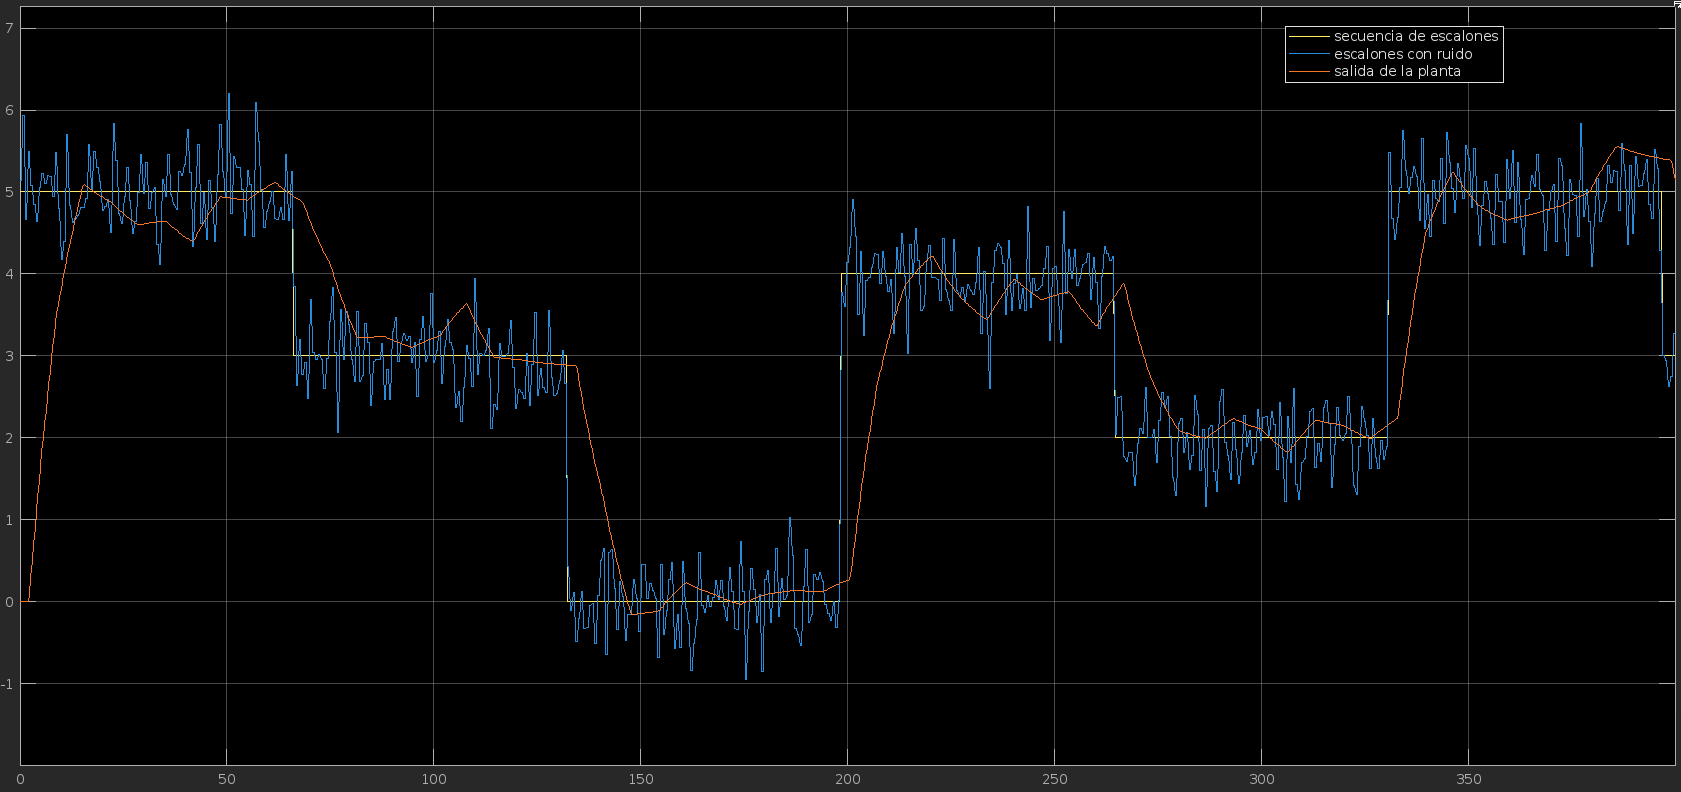

Fig: Desempeño de la planta en lazo cerrado con contorlador PI sintonizado ante cambios de entradas y perturbaciones.

**9) Comparar gráficamente el sistema de control antes de sintonizarse y luego de sintonizarse con el método de lugar geométrico de las raíces y el comando rlocus de matlab.**

Función de transferencia en tiempo discreto del controlador PI antes de sintonizarse :

D1 = tf([q0_pi q1_pi],[1 -1],Ts)

D1 =
 
  17.01 z - 6.045
  ---------------
       z - 1
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


model1_la = series(D1,Fd) , model1_lc = feedback(model1_la,1) % El modelo controlador + planta en lazo abierto y cerrado

model1_la =
 
    0.3532 z - 0.1255
  ----------------------
  z^2 - 1.656 z + 0.6562
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties

model1_lc =
 
    0.3532 z - 0.1255
  ----------------------
  z^2 - 1.303 z + 0.5307
 
Sample time: 6.6139 seconds
Discrete-time transfer function.


Y despues de sintonizarse :

D2 = tf([q0_pi_s q1_pi_s],[1 -1],Ts)  % modelo controlador sintonizado + planta en lazo abierto.

D2 =
 
  32.63 z - 23.37
  ---------------
       z - 1
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties


model2_la = series(D2,Fd), model2_lc = feedback(model2_la,1) % modelo controlador sintonizado + planta en lazo abierto y cerrado.

model2_la =
 
    0.6775 z - 0.4853
  ----------------------
  z^2 - 1.656 z + 0.6562
 
Sample time: 6.6139 seconds
Discrete-time transfer function.
Model Properties

model2_lc =
 
     0.6775 z - 0.4853
  -----------------------
  z^2 - 0.9787 z + 0.1709
 
Sample time: 6.6139 seconds
Discrete-time transfer function.


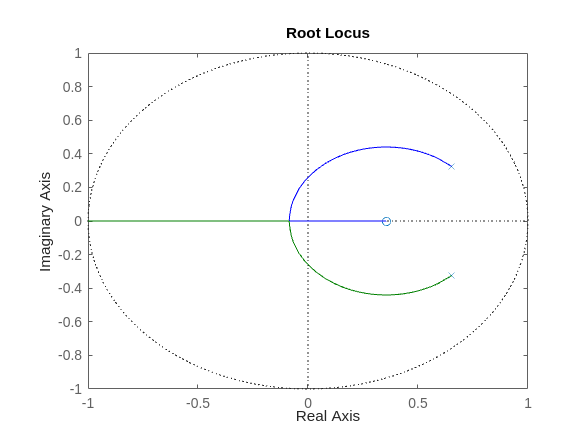

rlocus(model1_lc)

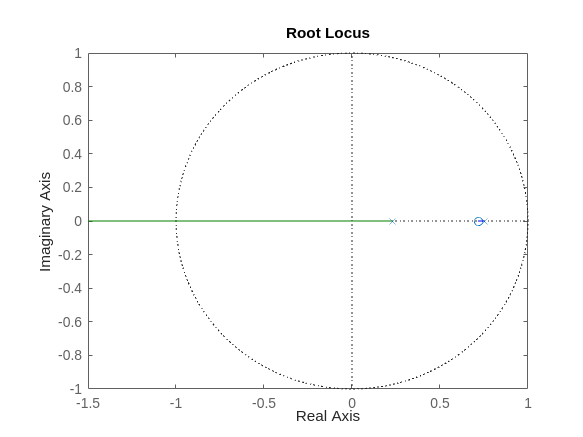

rlocus(model2_lc)

La función Root locus nos ubica los polos del sistema en lazo cerrado para valores de ganancia entre 0 y el infinito.

El grafico root locus para el modelo con PI no sintonizado nos indica que tiene polos con una parte real positiva, lo que normalmente genera inestabilidad. Se sabe que un sistema con retraso puede generar inestabilidad, y en este caso es muy dificil de interpretar el grafico. Para quitar esta inestabilidad, podriamos agregar un compensador. Se indentifican 2 polos.

El segundo grafico nos muestra los polos del modelo con PI sintonizado. Tiene 2 polos reales Un polo es positivo para frecuencias muy altas (la cruz representa el infinito) y el otro siempre es positivo. Para frecuencias bajas, este modelo tiene apenas un solo polo real positivo lo que lo hace mas estable que el PI que no esta sintonizado.

Cuando no tiene parte imaginaria, significa que la respuesta no tiene oscilaciones. Eso lo comprobamos con el grafico encima por el hecho de que el controlador sintonizado no tiene sobreimpulsos.